### Load in data and combine

cd("C:\Users\djlasky\OneDrive - University of California, Davis\Documents\UC Davis\Usrey Lab\Analysis");

data1 = load("AttentionAudioFeedback_1.mat");
data2 = load("AttentionAudioFeedback_2.mat");

redChanges      = [data1.redChangesThisTrial; data2.redChangesThisTrial];
greenChanges    = [data1.greenChangesThisTrial; data2.greenChangesThisTrial];
trialCorrect    = [data1.trialCorrect; data2.trialCorrect];
trialValidity   = [data1.valid; data2.valid];
trialRT         = [data1.trialRT; data2.trialRT];

### General Prep

trialValid      = trialValidity == 1;
trialInvalid    = trialValidity == 0;
trialCatch      = trialValidity == -1;

trialsPerBlock = length(redChanges);
trialBlocks = height(redChanges);

### Prepare trials correct by color

validRedChange          = trialValid & redChanges == 1;
validGreenChange        = trialValid & greenChanges == 1;
correctValidRedChange   = trialCorrect == 1 & trialValid & redChanges == 1;
correctValidGreenChange = trialCorrect == 1 & trialValid & greenChanges == 1;

invalidRedChange            = trialInvalid & redChanges == 1;
invalidGreenChange          = trialInvalid & greenChanges == 1;
correctInvalidRedChange     = trialCorrect == 1 & trialInvalid & redChanges == 1;
correctInvalidGreenChange   = trialCorrect == 1 & trialInvalid & greenChanges == 1;

perCorrectValidRedChange   = sum(correctValidRedChange, "all") / sum(validRedChange, "all") * 100;
perCorrectValidGreenChange = sum(correctValidGreenChange, "all") / sum(validGreenChange, "all") * 100;

perCorrectInvalidRedChange   = sum(correctInvalidRedChange, "all") / sum(invalidRedChange, "all") * 100;
perCorrectInvalidGreenChange = sum(correctInvalidGreenChange, "all") / sum(invalidGreenChange, "all") * 100;

### Plot valid trials correct by color

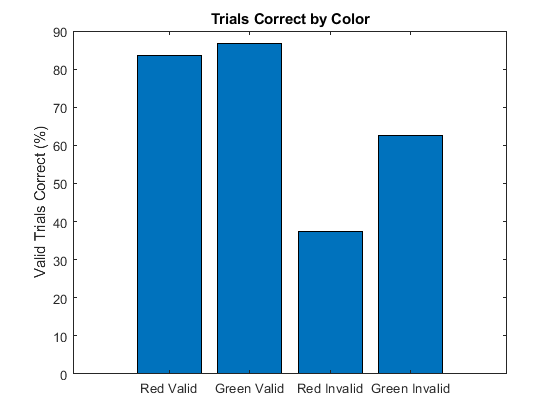

bar([perCorrectValidRedChange, perCorrectValidGreenChange, perCorrectInvalidRedChange, perCorrectInvalidGreenChange])
title("Trials Correct by Color")
xticklabels(["Red Valid", "Green Valid", "Red Invalid", "Green Invalid"])
ylabel("Valid Trials Correct (%)")
saveas(gcf, "Correct Trials By Color.png")

### Prepare percentage correct by trial type

correctValid    = trialCorrect == 1 & trialValid;
correctInvalid  = trialCorrect == 1 & trialInvalid;
correctCatch    = trialCorrect == 1 & trialCatch;

totalCorrectValid   = sum(correctValid, "all") / sum(trialValid, "all") * 100;
totalCorrectInvalid = sum(correctInvalid, "all") / sum(trialInvalid, "all") * 100;
totalCorrectCatch   = sum(correctCatch, "all") / sum(trialCatch, "all") * 100;

indivCorrectValid   = sum(correctValid, 2) ./ sum(trialValid, 2) * 100;
indivCorrectInvalid = sum(correctInvalid, 2) ./ sum(trialInvalid, 2) * 100;
indivCorrectCatch   = sum(correctCatch, 2) ./ sum(trialCatch, 2) * 100;

xVal = [ones(trialBlocks, 1); 2 * ones(trialBlocks, 1); 3 * ones(trialBlocks, 1)];

### Plot percentage correct by trial type

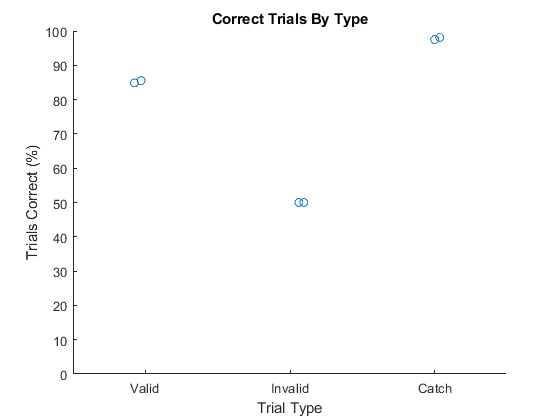

s = swarmchart(xVal, [indivCorrectValid; indivCorrectInvalid; indivCorrectCatch]);
s.XJitterWidth = 0.25;
ylim([0 100])
xticks([1 2 3])

title("Correct Trials By Type")
xticklabels(["Valid", "Invalid", "Catch"])
xlabel("Trial Type")
ylabel("Trials Correct (%)")
saveas(gcf, "Correct Trials By Type.png")

### Prepare reaction time by trial type

validRT         = trialRT(trialValid & ~isnan(trialRT));
invalidRT       = trialRT(trialInvalid & ~isnan(trialRT));
catchRT         = trialRT(trialCatch & ~isnan(trialRT));

validRT_Mn      = mean(validRT);
invalidRT_Mn    = mean(invalidRT);
catchRT_Mn      = mean(catchRT);

validRT_SEM     = std(validRT) / sqrt(length(validRT));
invalidRT_SEM   = std(invalidRT) / sqrt(length(invalidRT));
catchRT_SEM     = std(catchRT) / sqrt(length(catchRT));

xVal2 = [ones(length(validRT), 1); 2 * ones(length(invalidRT), 1); 3 * ones(length(catchRT), 1)];

### Plot reaction time by trial type

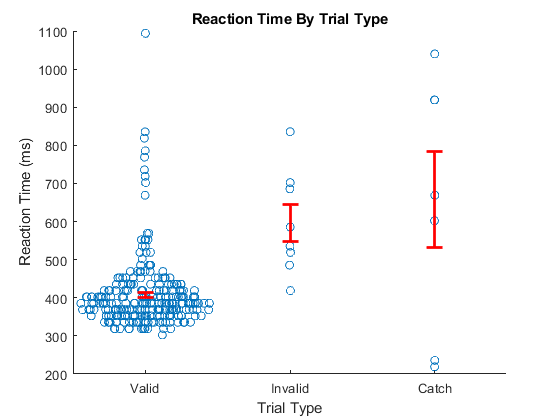

s = swarmchart(xVal2, [validRT; invalidRT; catchRT]);
hold on
eb(1) = errorbar(1, validRT_Mn, validRT_SEM, "r", "LineWidth", 2, "CapSize", 12);
eb(2) = errorbar(2, invalidRT_Mn, invalidRT_SEM, "r", "LineWidth", 2, "CapSize", 12);
eb(3) = errorbar(3, catchRT_Mn, catchRT_SEM, "r", "LineWidth", 2, "CapSize", 12);
hold off
xticks([1 2 3])

title("Reaction Time By Trial Type")
xticklabels(["Valid", "Invalid", "Catch"])
xlabel("Trial Type")
ylabel("Reaction Time (ms)")
saveas(gcf, "Reaction Time By Trial Type.png")